# **ACM 11 Homework 1 Part 2/2 (Spring 2024)**

## **Due Friday, April 12, 11:59pm Pacific Time, by upload to Canvas.**

This portion of the assignment is worth $25$ points. 

Parts **a), b), c) **are theoretical questions that will involve showing your work. You may submit answers to these parts through the following methods:

- You may write in this `MATLAB` script directly underneath the questions.

- You may work on your iPad, paper or LaTeX, and attached the .pdf in your Canvas Submission. 

Part **d)** is an implementation question and will involve writing code from scratch. 

### **Problem 6 (Properties of Forward Euler, 25 points)**

In lecture $1$, we discussed how to use the forward Euler method to numerically approximate the solution for complicated ODEs where it is often not possible to obtain a closed-form solution. However, it might be useful to observe the theoretical properties held by the Forward Euler method on a simple ODE by comparing the approximation to the true solution. Consider the linear ODE:


$$$$\frac{d\phi}{dt} = 2t$$$$


Let $\phi$ be the solution to the ODE above, with the initial condition that $\phi(0) = 0$.

**(5 points) **What is the true solution $\phi(1)$ using the analytical solution for $\phi(t)$?

**(5 points) **Write the forward Euler approximation for $\phi(1)$ using $2$ steps of equal length beteen $t = 0$ and $t=1$. Write it also for $3$ steps of equal length.

**(5 points) **Write the forward Euler approximation for $\phi(1)$ using $n$ steps of equal length, for any natural number $n$. Does the forward Euler approximation converge to $\phi(1)$ as $n \rightarrow \infty$? Explain why or why not by deriving the absolute error between the approximate solution and the true solution for $\phi$ at $t = 1$.

**(10 points) **Implement the forward Euler approximation for the ODE and generate two plots: 

- The value of the forward Euler approximation against time on the interval $[0,1]$ for $n = \{4,16,64,256\}$ steps. For the plot, you only need to evaluate the approximation at the grid points defined by discretizing the interval.

- The absolute error between the forward Euler approximation and the true solution $\phi(t)$ against time on the interval $[0,1]$ using $n = \{4,16,64,256\}$ steps.

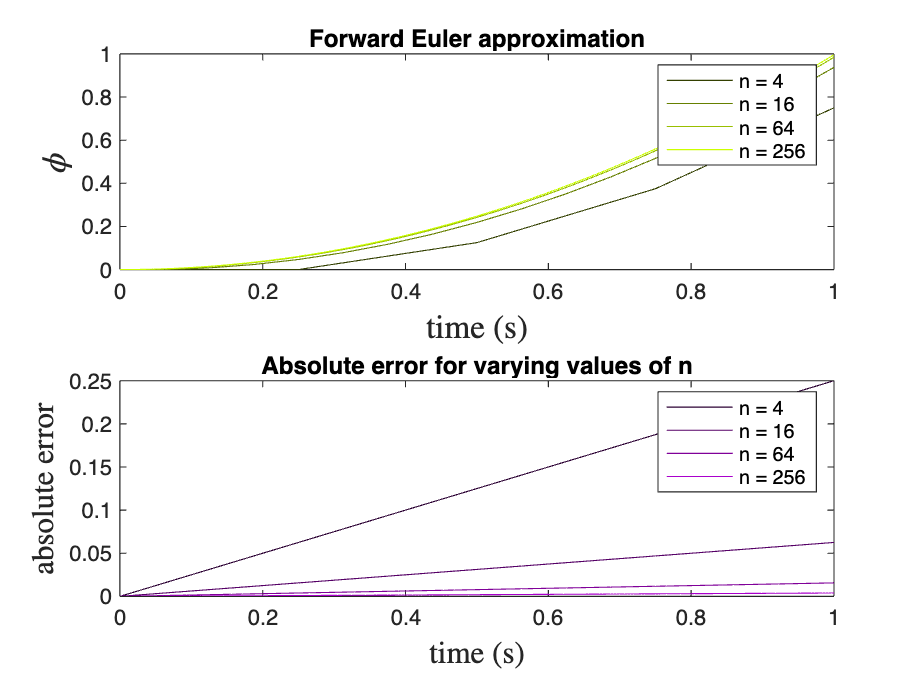

f = @(t,u) 2*t;
plots = zeros(1, 4);
labels = cell(1, 4);
errorPlots = zeros(1, 4);
errorLabels = cell(1, 4);

phi_0 = 0;
t_0 = 0;
uFE_0 = phi_0;
T = 1;            
             
for j=1:4
    K = (2^j)^2;
    dt = T/K; 
    t = 0:dt:T;        
    uFE = zeros(1,K+1);
    error = zeros(1,K+1);
    uFE(1) = uFE_0;
   
    error(1) = abs(uFE(1) - 0);
    for i = 2:(K +1)                        
        uFE(i) = uFE(i-1) + dt*f(t(i-1),uFE(i-1));
        error(i) = abs(uFE(i) - ((i-1)/K)^2);
    end
    hold on;
    subplot(2, 1, 1);
    plots(j) = plot(t,uFE(1,:),'Color', [j/5 j/4 0]);
    labels{j} = ['n = ', num2str((2^j)^2)];
    hold off;
    hold on;
    subplot(2, 1, 2);
    errorPlots(j) = plot(t, error(1,:), 'Color', [j/6 0 j/5]);
    errorLabels{j} = ['n = ', num2str((2^j)^2)];
    hold off;
end

hold off;
subplot(2, 1, 1);
xlabel('time (s)','FontSize',15, 'Interpreter', "latex");
ylabel('$\phi$', 'FontSize',15,'Interpreter',"latex");
title('Forward Euler approximation')
legend(plots, labels);
legend(errorPlots, errorLabels);
subplot(2, 1, 2);
xlabel('time (s)','FontSize',14, 'Interpreter', "latex");
ylabel('absolute error', 'FontSize',14,'Interpreter',"latex");
title('Absolute error for varying values of n')

Explain (in a paragraph) why the derivations done in **a) - c)** agree with the plots generated in **d)**.